# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 200; % # sample points
A = 21; % Magnitude/Amplitude of droplet
c1 = 0.001264379882813;
c2 = 0.016807519531250;
tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
xI0 = -5;
xB0 = 11;
xC0 = 12;

**Target Shape **`h_target`

h_target = 0.1*ones(size(X));
h_target(2.5 - X.^2/12>0.1) = 2.5 - X(2.5 - X.^2/12>0.1).^2/12;

## **2) **

**Solutions**

Inside

[tSpanI,D1,D2,X,H0I,myObjective_Possition,conds_SolI,...
    fvalI,exitflagI,outputI,historyI,HistoryI,h_SolI,H_SolI]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,xI0,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          112.007         
     1            2          112.007         initial simplex
     2            4          102.843         expand
     3            6          82.5146         expand
     4            8          37.6085         expand
     5           10          13.9529         reflect
     6           12          13.9529         contract inside
     7           14           4.9529         contract inside
     8           16           4.9529         contract inside
     9           18           4.9529         contract inside
    10           20           4.9529         contract outside
    11           22           4.9529         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 




nI = size(historyI);
nI1 = nI(1)-2;
dataHI = historyI(2:8)';
dataHIi = abs(historyI(2:end))';
lineHI = 0:1:6;
lineHIi = 0:1:nI1;
[pI,SI,muI] = polyfit(lineHI,dataHI,1);
[pHI,deltaI] = polyval(pI,lineHI,SI,muI);
xIi = linspace(0, nI1, 100); 
yIi = interp1(lineHIi, dataHIi, xIi, 'spline', 'extrap');



Boarder

[tSpanB,D1,D2,X,H0B,myObjective_Possition,conds_SolB,...
    fvalB,exitflagB,outputB,historyB,HistoryB,h_SolB,H_SolB]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,xB0,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1           168.45         
     1            2           168.45         initial simplex
     2            4          167.636         expand
     3            6          152.542         expand
     4            8          78.2287         expand
     5           10          28.1984         reflect
     6           12          28.1984         contract inside
     7           14           4.9529         contract inside
     8           16           4.9529         contract inside
     9           18           4.9529         contract inside
    10           20           4.9529         contract inside
    11           23           4.9529         shrink
    12           25           4.9529         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 




nB = size(historyB);
nB1 = nB(1)-2;
dataHB = historyB(2:8)';
dataHBi = abs(historyB(2:end))';
lineHB = 0:1:6;
lineHBi = 0:1:nB1;
[pB,SB,muB] = polyfit(lineHB,dataHB,1);
[pHB,deltaB] = polyval(pB,lineHB,SB,muB);
xBi = linspace(1, nB1, 100); 
yBi = interp1(lineHBi, dataHBi, xBi, 'spline', 'extrap');



Outside

[tSpanC,D1,D2,X,H0C,myObjective_Possition,conds_SolC,...
    fvalC,exitflagC,outputC,historyC,HistoryC,h_SolC,H_SolC]...
    = Possition(tfinal,dx,X,k,y0,N,A,c1,c2,xC0,h_target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          168.451         
     1            2          168.451         initial simplex
     2            5          168.451         shrink
     3            8          168.451         shrink
     4           10          168.451         reflect
     5           13          168.451         shrink
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 




nC = size(historyC);
nC1 = nC(1)-2;
dataHC = historyC(2:end)';
dataHCi = abs(historyC(2:end))';
lineHC = 0:1:nC1;
lineHCi = 0:1:nC1;
[pC,SC,muC] = polyfit(lineHC,dataHC,1);
[pHC,deltaC] = polyval(pC,lineHC,SC,muC);
xCi = linspace(0, nC1, 100); 
yCi = interp1(lineHCi, dataHCi, xCi, 'spline', 'extrap');



**Inside Figures**

Fig. 0

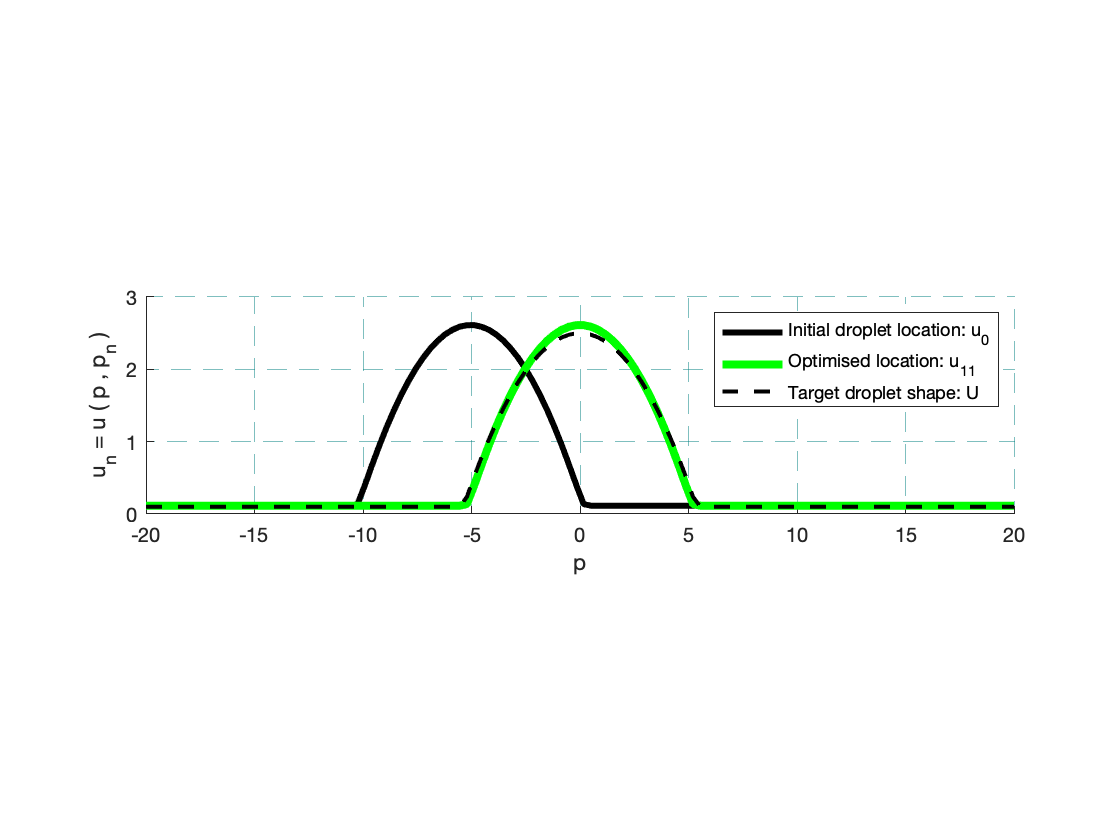


figure;
hold on
plot(X,H0I,'k-','linewidth',3);
plot(X,H_SolI,'g-','linewidth',4);
plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 3]);
xlabel('p');
ylabel('u_n = u ( p , p_n )');
grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
% title('2-D profile of droplet');
legend('Initial droplet location: u_0','Optimised location: u_{11}','Target droplet shape: U','Location','northeast');
hold off

Fig. 1

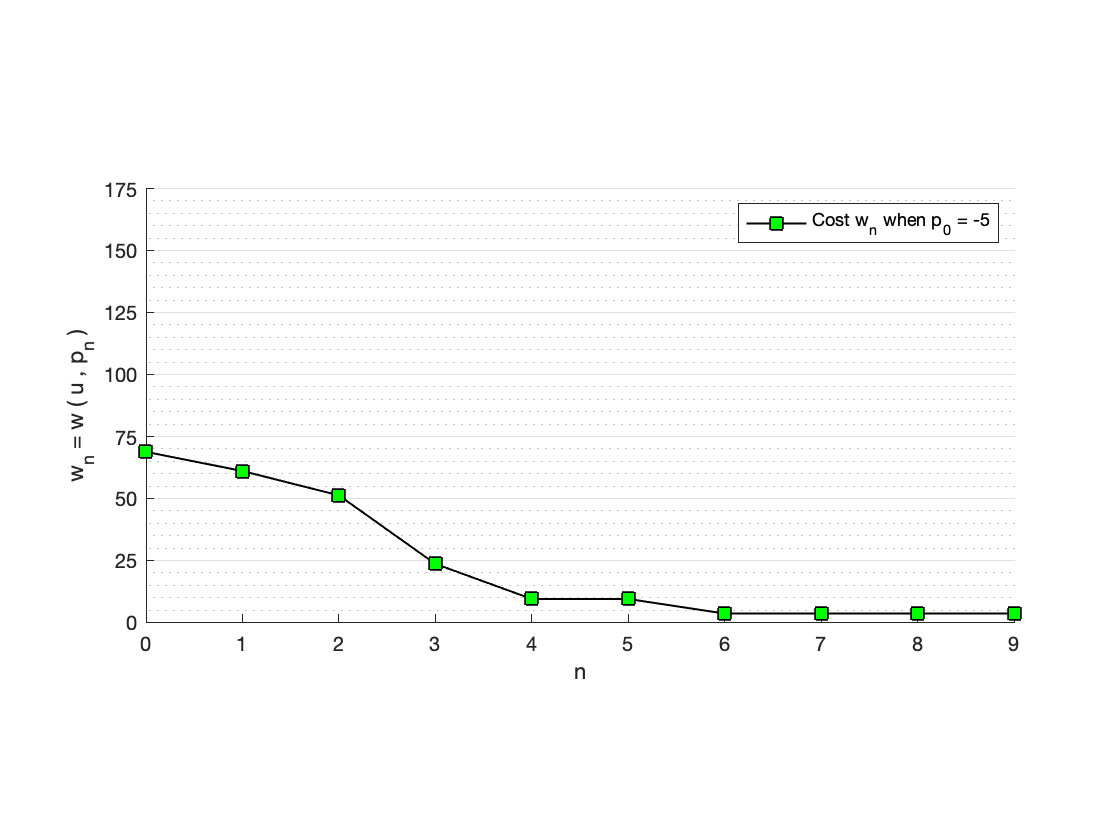


figure;
hold on
plot(lineHIi,HistoryI(2:end),'k-s',...
    'MarkerSize',8,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
% title('Iterative evolution of droplet distance to optimal location');
ylabel('w_n = w ( u , p_n )');
xlabel('n');
legend('Cost w_n when p_0 = -5');
set(gca,'xtick',0:1:100);
set(gca,'ytick',-100:25:200);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
xlim([0 nI1]);
ylim([0 175]);
pbaspect([2 1 1]);
box off
hold off

Fig. 2

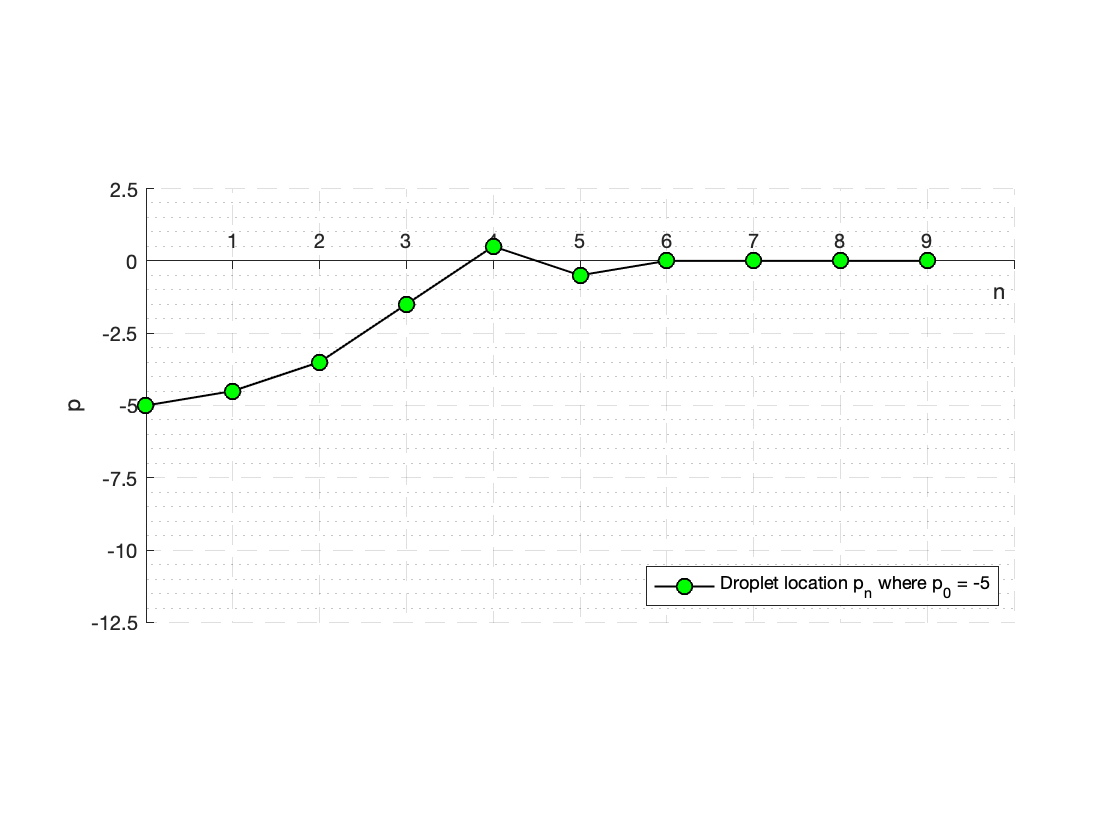


figure;
hold on
plot(lineHIi,historyI(2:end),'k-o',...
    'MarkerSize',8,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
% title('Iterative evolution of droplet distance to optimal location');
ylabel('p');
xlabel('n');
legend('Droplet location p_n where p_0 = -5','Location','southeast');
set(gca,'xtick',0:1:13);
set(gca,'ytick',-15:2.5:100);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.XAxisLocation = 'origin';
xlim([0 nI1+1]);
ylim([-12.5 2.5]);
pbaspect([2 1 1]);
box off
hold off

we see a faily straight line for the first 6 iterations  with a logspace x (iterations) axis

**Boarder Figures**

Fig. 0

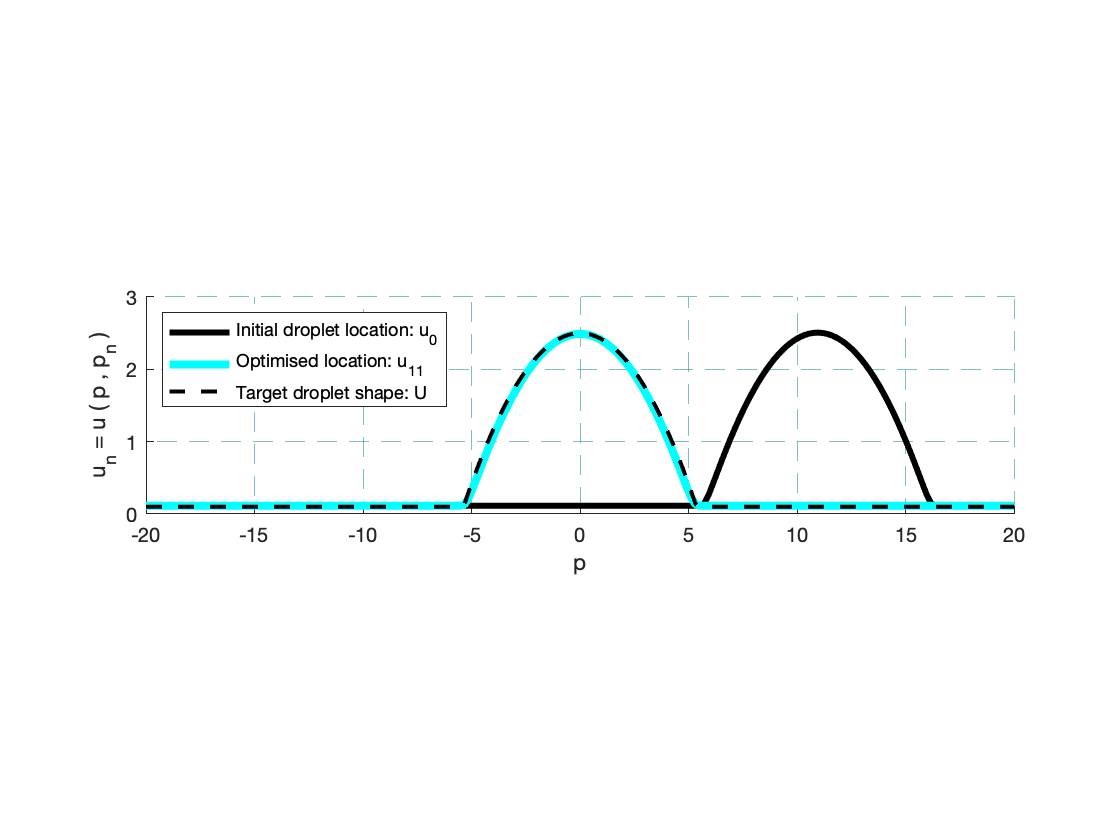


figure;
hold on
plot(X,H0B,'k-','linewidth',3);
% plot(X,HI1,'k:','linewidth',4);
plot(X,H_SolB,'c-','linewidth',4);
plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 3]);
xlabel('p');
ylabel('u_n = u ( p , p_n )');
grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
% title('2-D profile of droplet');
legend('Initial droplet location: u_0','Optimised location: u_{11}','Target droplet shape: U','Location','northwest');
hold off

Fig. 1

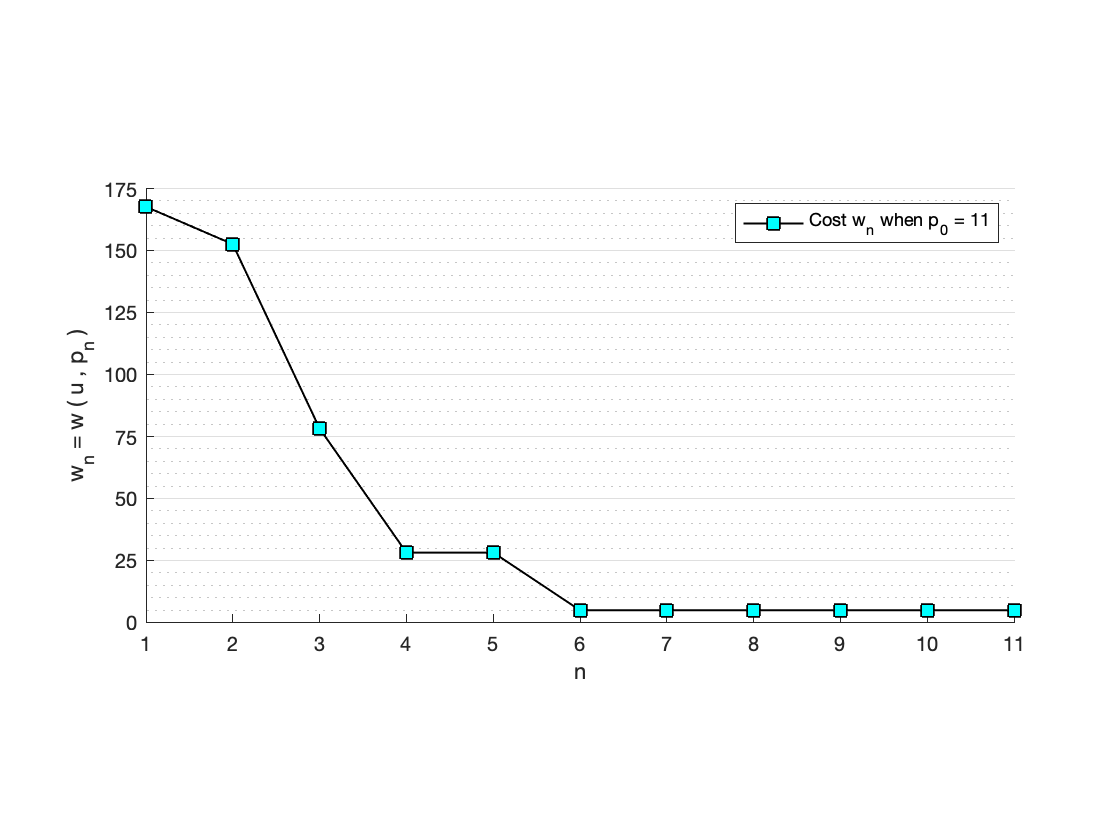


figure;
hold on
plot(lineHBi,HistoryB(2:end),'k-s',...
    'MarkerSize',8,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
% title('Iterative evolution of droplet distance to optimal location');
ylabel('w_n = w ( u , p_n )');
xlabel('n');
legend('Cost w_n when p_0 = 11');
set(gca,'xtick',0:1:100);
set(gca,'ytick',0:25:200);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
xlim([1 nB1]);
ylim([0 175]);
pbaspect([2 1 1]);
box off
hold off

Fig. 2

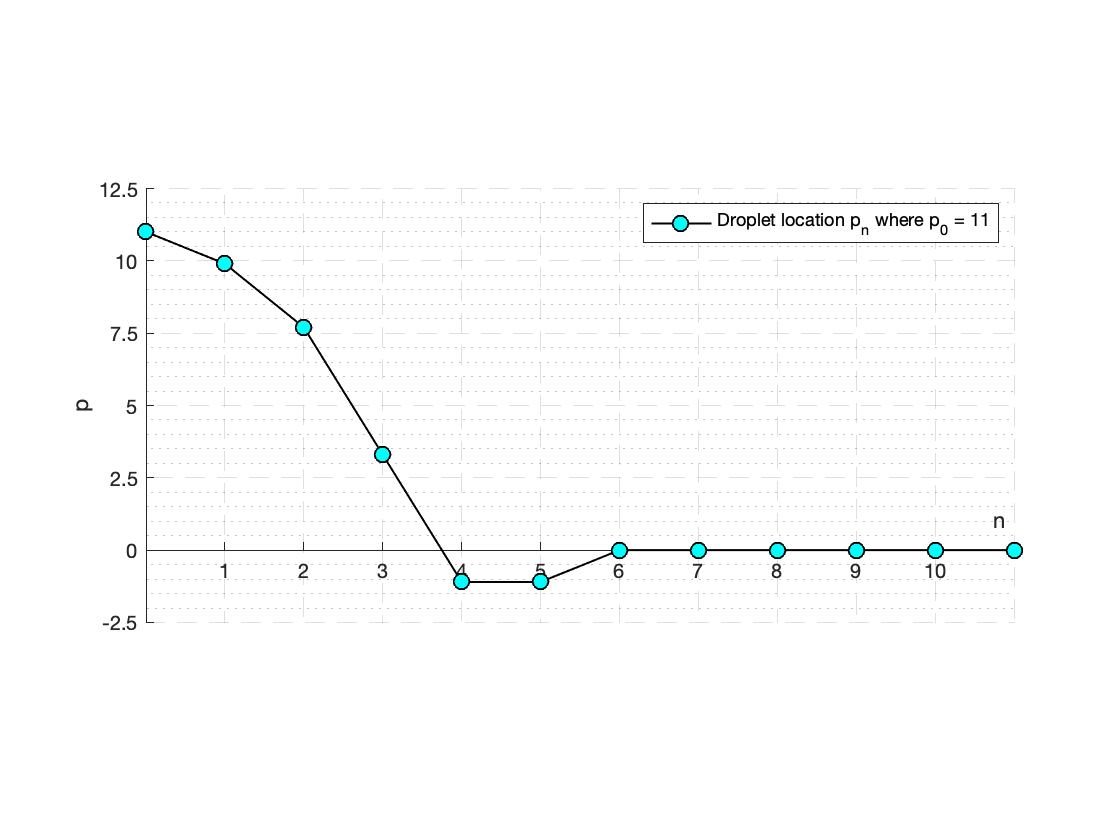


figure;
hold on
plot(lineHBi,historyB(2:end),'k-o',...
    'MarkerSize',8,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
% title('Iterative evolution of droplet distance to optimal location');
ylabel('p');
xlabel('n');
legend('Droplet location p_n where p_0 = 11');
set(gca,'xtick',0:1:20);
set(gca,'ytick',-2.5:2.5:100);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.XAxisLocation = 'origin';
xlim([0 nB1]);
ylim([-2.5 12.5]);
pbaspect([2 1 1]);
box off
hold off

we see a faily straight line for the first 6 iterations  with a logspace x (iterations) axis

**2nd - Boarder Figures**

Fig. 0

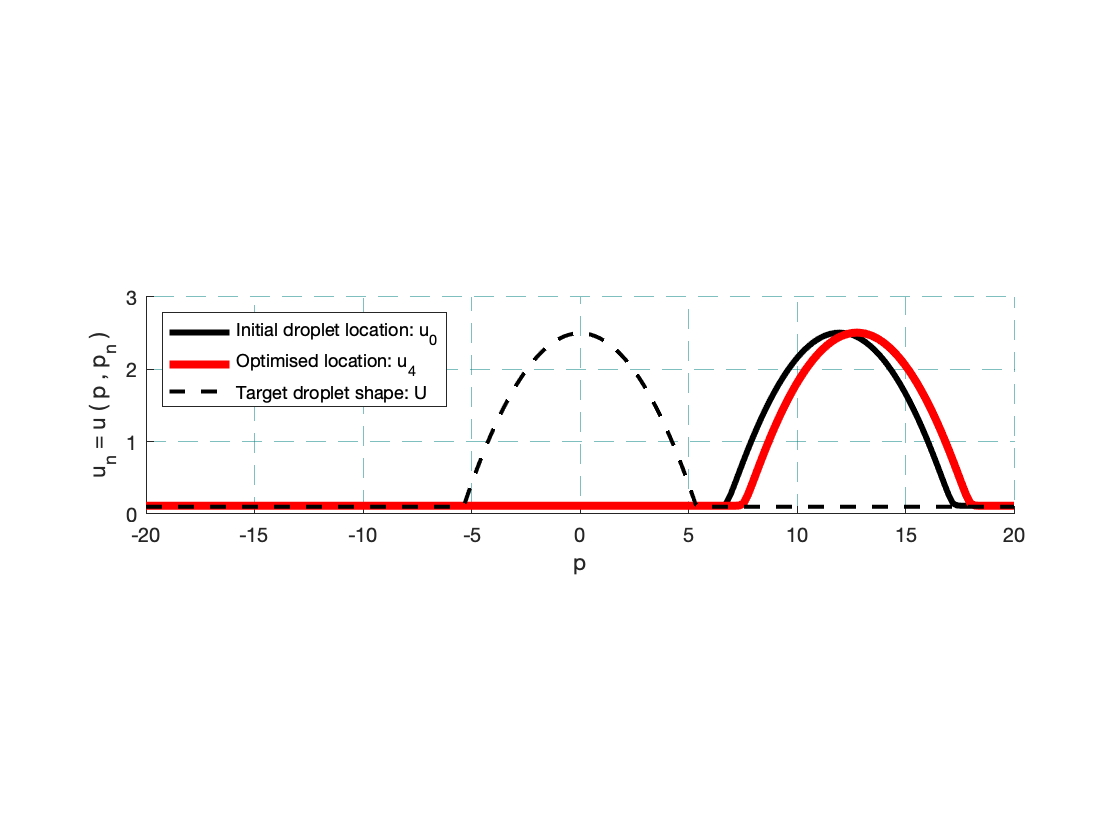


figure;
hold on
plot(X,H0C,'k-','linewidth',3);
% plot(X,HI1,'k:','linewidth',4);
plot(X,H_SolC,'r-','linewidth',4);
plot(X,h_target,'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 3]);
xlabel('p');
ylabel('u_n = u ( p , p_n )');
grid on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
% title('2-D profile of droplet');
legend('Initial droplet location: u_0','Optimised location: u_{4}','Target droplet shape: U','Location','northwest');
hold off

Fig. 1

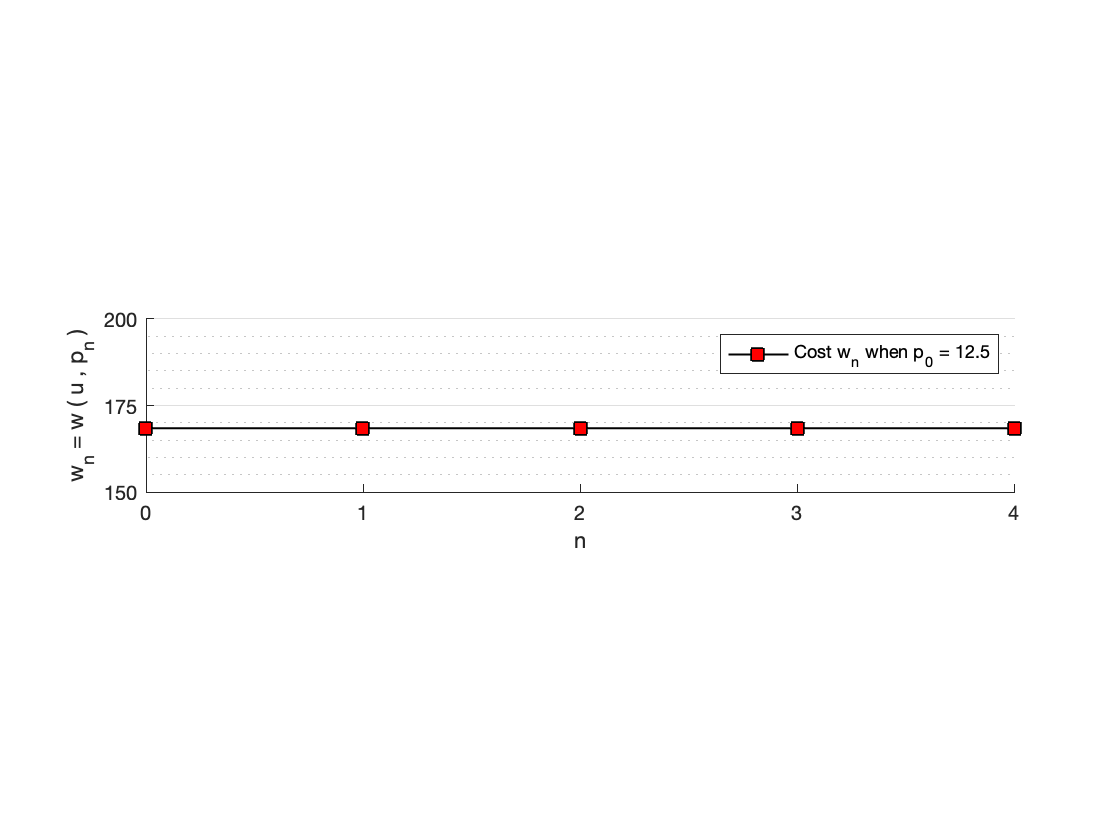


figure;
hold on
plot(lineHCi,HistoryC(2:end),'k-s',...
    'MarkerSize',8,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
% title('Iterative evolution of droplet distance to optimal location');
ylabel('w_n = w ( u , p_n )');
xlabel('n');
legend('Cost w_n when p_0 = 12.5');
set(gca,'xtick',0:1:100);
set(gca,'ytick',0:25:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
xlim([0 nC1]);
ylim([150 200]);
pbaspect([5 1 1]);
box off
hold off

Fig. 2

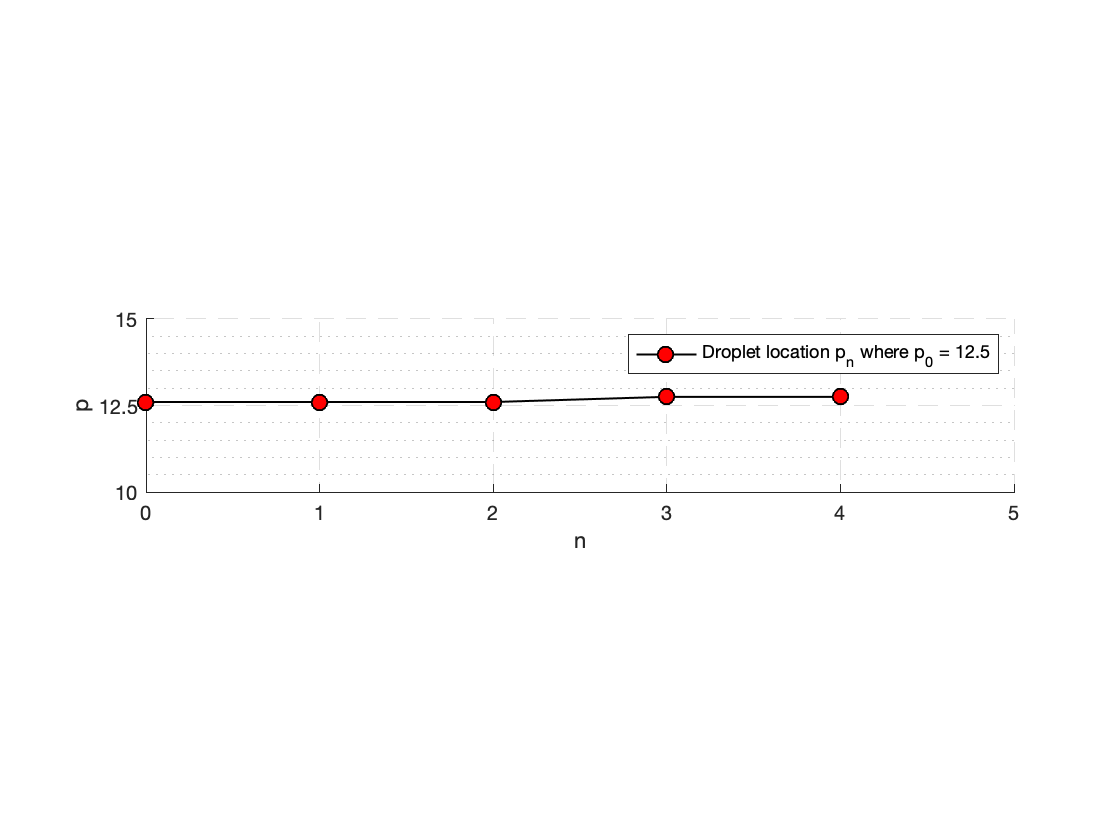


figure;
hold on
plot(lineHCi,historyC(2:end),'k-o',...
    'MarkerSize',8,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
% title('Iterative evolution of droplet distance to optimal location');
ylabel('p');
xlabel('n');
legend('Droplet location p_n where p_0 = 12.5');
set(gca,'xtick',0:1:21);
set(gca,'ytick',-2.5:2.5:100);
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.XAxisLocation = 'origin';
xlim([0 nC1+1]);
ylim([10 15]);
pbaspect([5 1 1]);
box off
hold off

we see a faily straight line for the first 6 iterations  with a logspace x (iterations) axis

**Joint Figures**

Joint Fig. 1

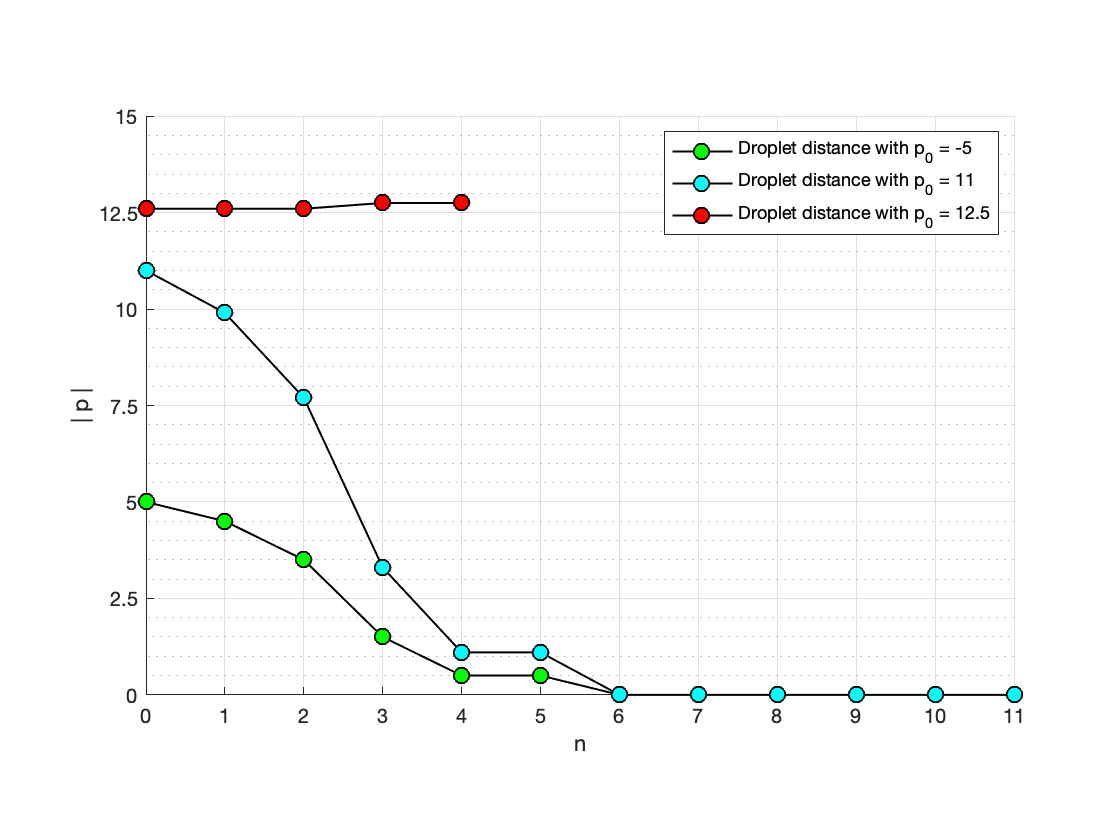


figure;
hold on
plot(lineHIi,dataHIi,'-ko',...
    'MarkerSize',8,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(lineHBi,dataHBi,'-ko',...
    'MarkerSize',8,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
plot(lineHCi,dataHCi,'-ko',...
    'MarkerSize',8,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
% title('Iterative evolution of droplet distance to optimal location');
ylabel('| p |');
xlabel('n');
legend('Droplet distance with p_0 = -5','Droplet distance with p_0 = 11','Droplet distance with p_0 = 12.5');
set(gca,'xtick',0:1:21);
set(gca,'ytick',0:2.5:100);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
ax.XAxisLocation = 'origin';
xlim([0 nB1]);
ylim([0 15]);
pbaspect([3 2 1]);
box off
hold off

Joint Fig. 2

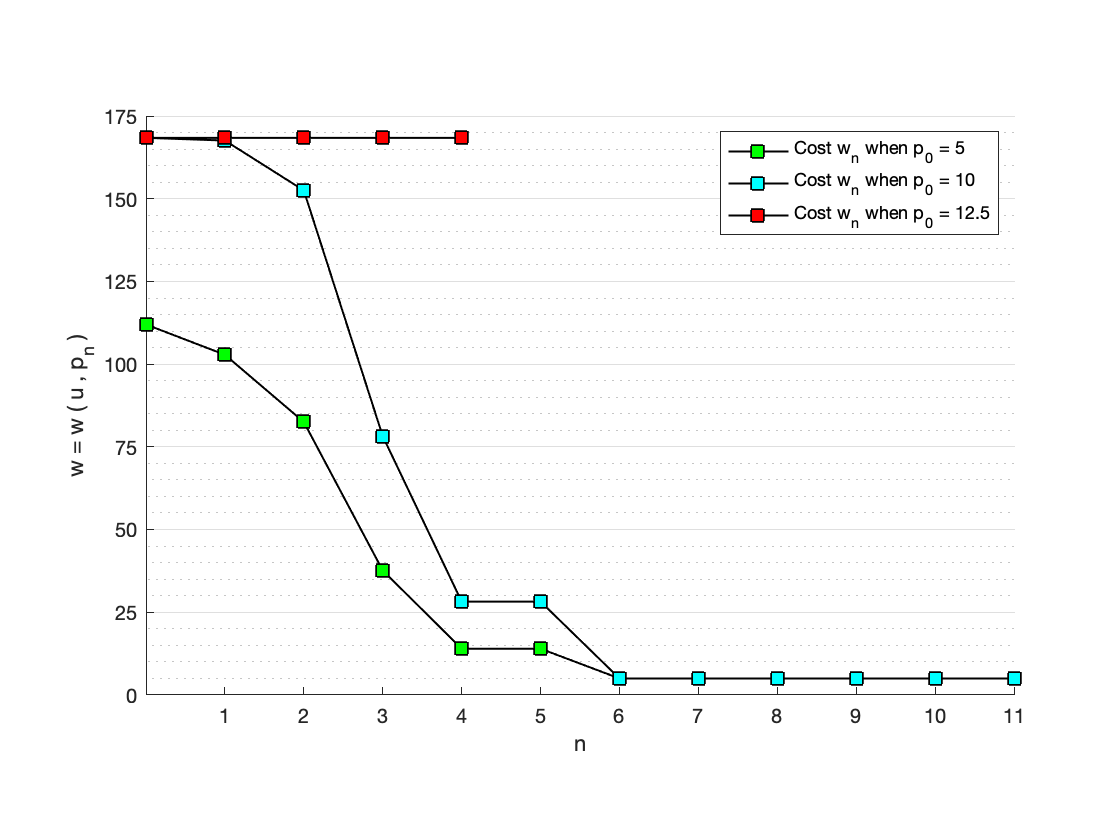


figure;
hold on
plot(lineHIi,HistoryI(2:end),'k-s',...
    'MarkerSize',8,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(lineHBi,HistoryB(2:end),'k-s',...
    'MarkerSize',8,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
plot(lineHCi,HistoryC(2:end),'k-s',...
    'MarkerSize',8,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
% title('Iterative evolution of droplet distance to optimal location');
ylabel('w = w ( u , p_n )');
xlabel('n');
legend('Cost w_n when p_0 = 5','Cost w_n when p_0 = 10','Cost w_n when p_0 = 12.5');
set(gca,'xtick',1:1:100);
set(gca,'ytick',0:25:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
xlim([0 nB1]);
ylim([0 175]);
pbaspect([3 2 1]);
box off
hold off